clear; close all; clc;
k = 4.66;
m1 = 0.0917;
m2 = 0.0765;

a1 = 0; a2 = 1; a3 = 0; a4 = 0;
b1 = 2*(-k/m1); b2 = 0; b3 = k/m1; b4 = 0;
c1 = 0; c2 = 0; c3 = 0; c4 = 1;
d1 = k/m2; d2 = 0; d3 = -k/m2; d4 = 0;
j = 100; k = 50;
T = 10;
N1 = 300; N2 = 500; N3 = 700;

[v_iem_1, w_iem_1, x_iem_1,y_iem_1,t_iem_1] = IEMSolver(a1,a2,a3,a4,b1,b2,b3,b4,c1,c2,c3,c4,d1,d2,d3,d4,j,k,T,N1);

ans =    0.0000 +11.8542i
   0.0000 -11.8542i
   0.0000 + 4.6935i
   0.0000 - 4.6935i


[v_iem_2, w_iem_2, x_iem_2,y_iem_2,t_iem_2] = IEMSolver(a1,a2,a3,a4,b1,b2,b3,b4,c1,c2,c3,c4,d1,d2,d3,d4,j,k,T,N2);

ans =    0.0000 +11.8542i
   0.0000 -11.8542i
   0.0000 + 4.6935i
   0.0000 - 4.6935i


[v_iem_3, w_iem_3, x_iem_3,y_iem_3,t_iem_3] = IEMSolver(a1,a2,a3,a4,b1,b2,b3,b4,c1,c2,c3,c4,d1,d2,d3,d4,j,k,T,N3);

ans =    0.0000 +11.8542i
   0.0000 -11.8542i
   0.0000 + 4.6935i
   0.0000 - 4.6935i


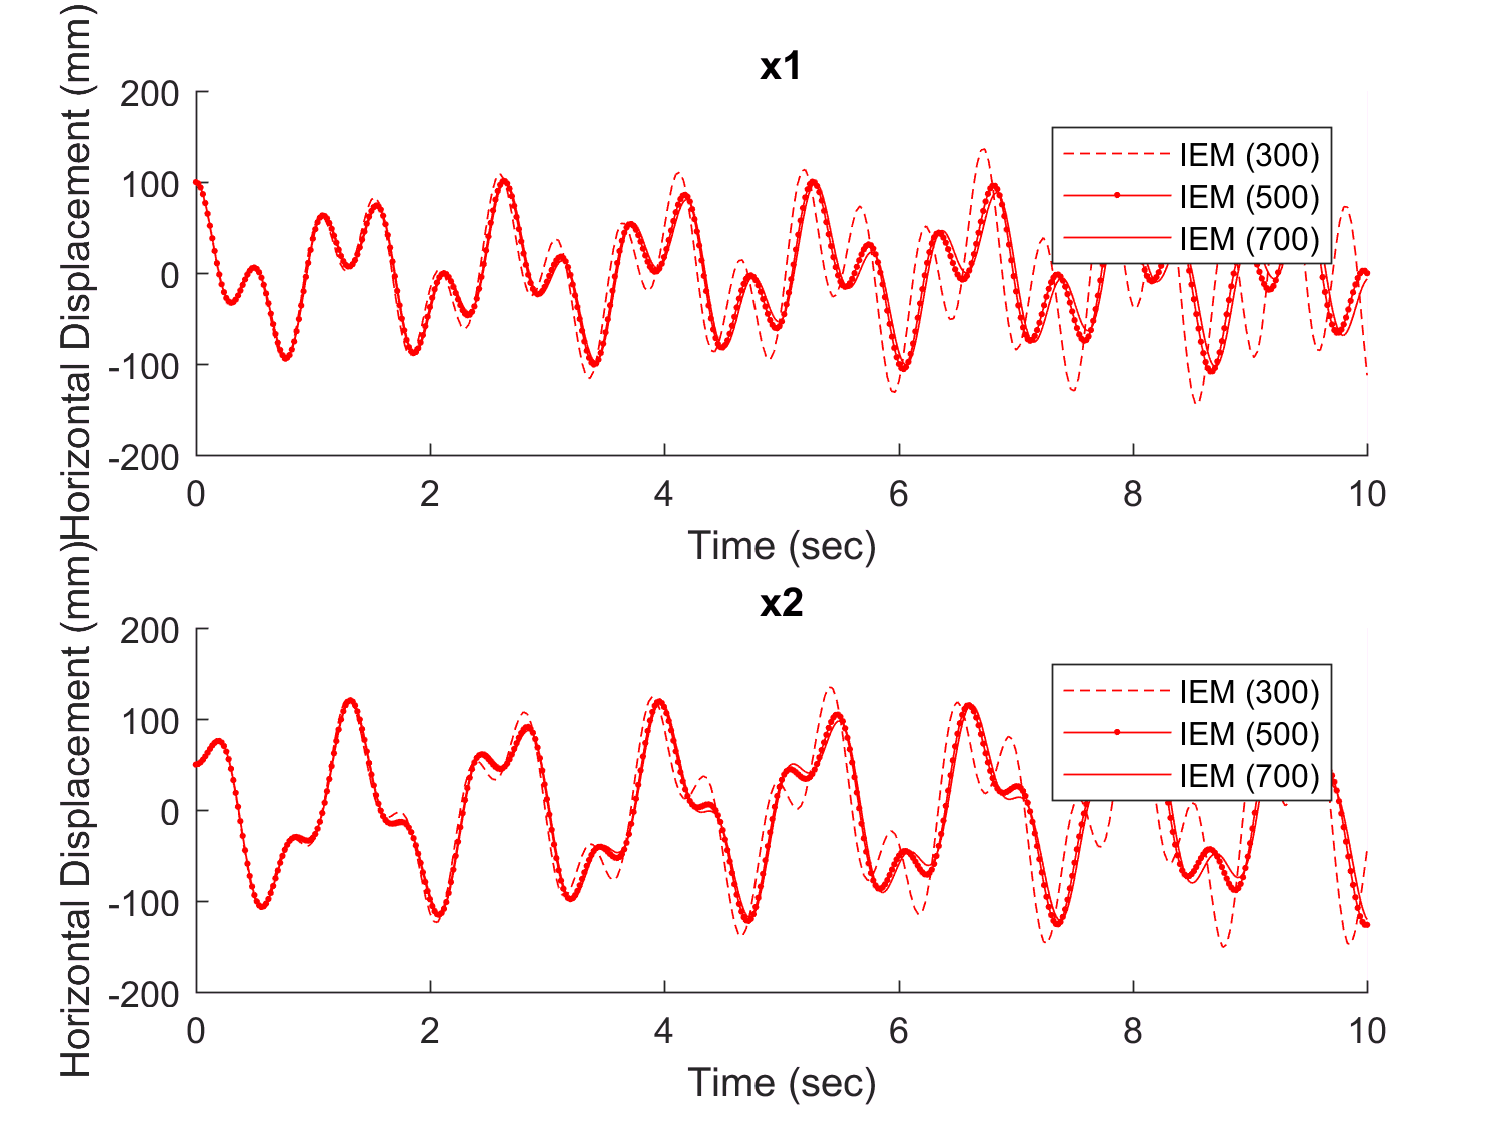


subplot(2,1,1);
hold on
plot(t_iem_1, v_iem_1,'--r');
plot(t_iem_2, v_iem_2,'.-r');
plot(t_iem_3, v_iem_3,'-r');
hold off

legend('IEM (300)','IEM (500)','IEM (700)')
xlabel('Time (sec)')
ylabel('Horizontal Displacement (mm)')
title('x1')

subplot(2,1,2);
hold all
plot(t_iem_1, x_iem_1,'--r');
plot(t_iem_2, x_iem_2,'.-r');
plot(t_iem_3, x_iem_3,'-r');
hold off

legend('IEM (300)','IEM (500)','IEM (700)')
xlabel('Time (sec)')
ylabel('Horizontal Displacement (mm)')
title('x2')

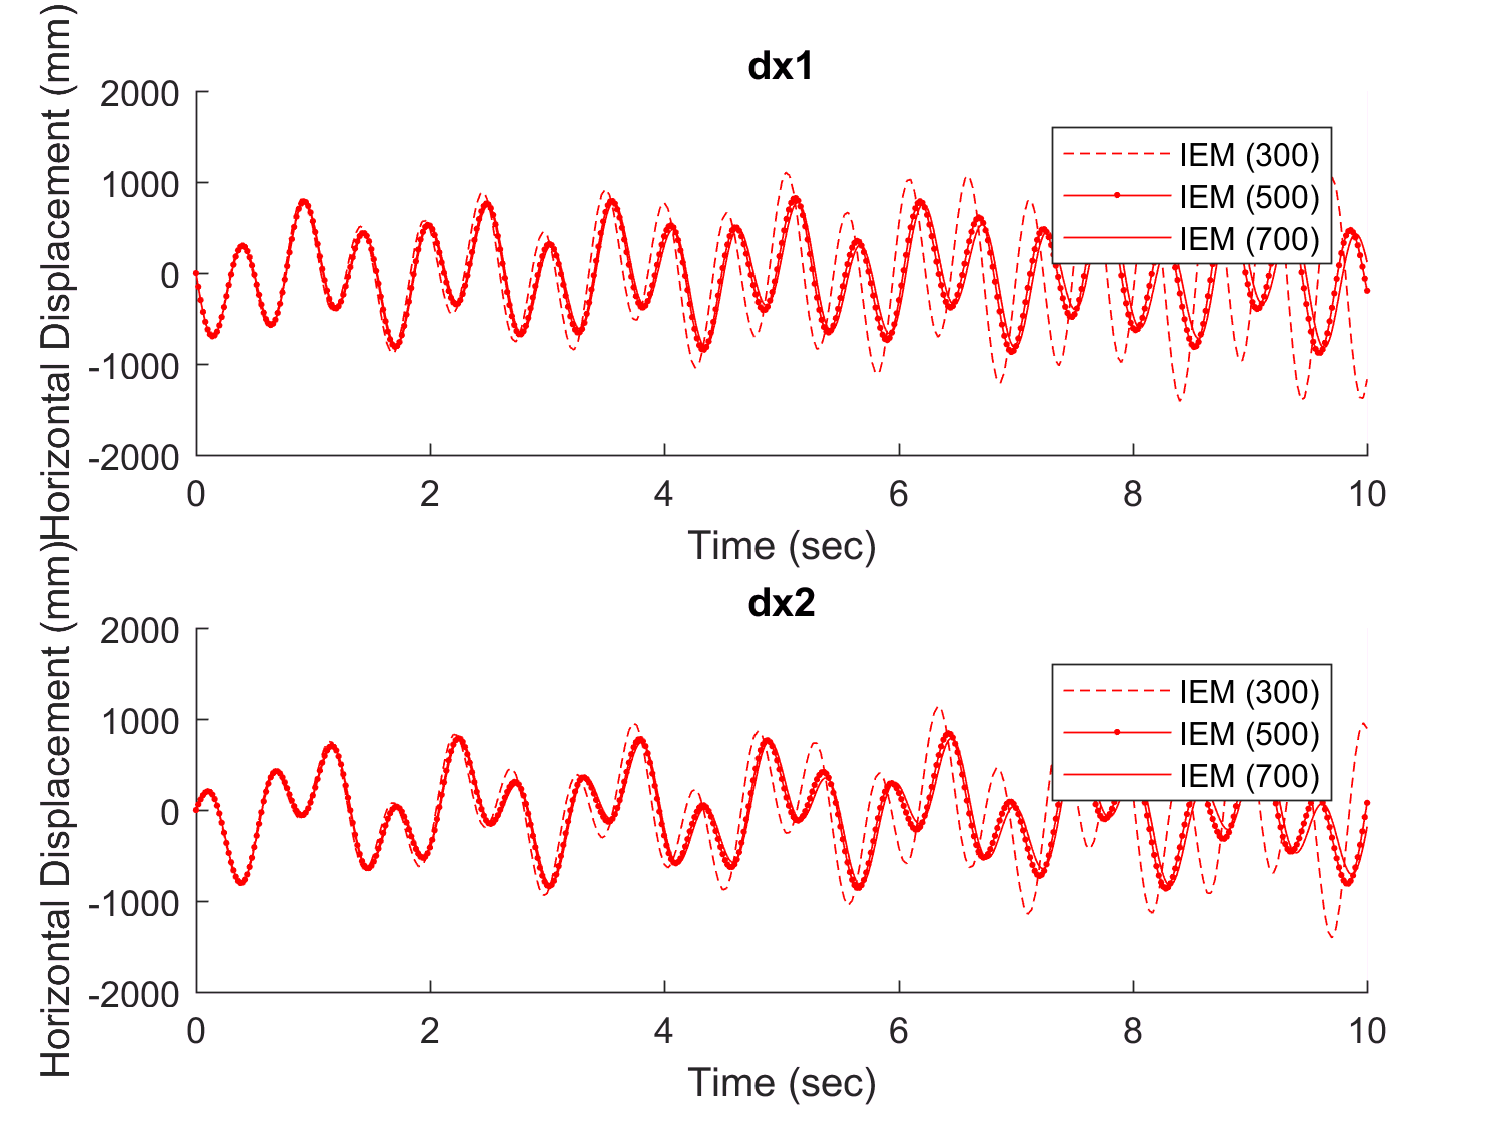


%derivatives
figure
subplot(2,1,1);
hold on
plot(t_iem_1, w_iem_1,'--r');
plot(t_iem_2, w_iem_2,'.-r');
plot(t_iem_3, w_iem_3,'-r');
hold off

legend('IEM (300)','IEM (500)','IEM (700)')
xlabel('Time (sec)')
ylabel('Horizontal Displacement (mm)')
title('dx1')

subplot(2,1,2);
hold all
plot(t_iem_1, y_iem_1,'--r');
plot(t_iem_2, y_iem_2,'.-r');
plot(t_iem_3, y_iem_3,'-r');
hold off

legend('IEM (300)','IEM (500)','IEM (700)')
xlabel('Time (sec)')
ylabel('Horizontal Displacement (mm)')
title('dx2')

function [v,w,x,y,t] = IEMSolver(a1,a2,a3,a4,b1,b2,b3,b4,c1,c2,c3,c4,d1,d2,d3,d4,j,k,T,N)
    A = [a1,a2,a3,a4;b1,b2,b3,b4;c1,c2,c3,c4;d1,d2,d3,d4];
    eig(A)
    dt = T/N;
    t = 0:dt:T;
    SOL = NaN(4,length(t));
    SOL(1,1) = j;
    SOL(2,1) = 0;
    SOL(3,1) = k;
    SOL(4,1) = 0;
    
    for z = 2:length(t)
        EM = SOL(:,z-1) + dt*A*SOL(:,z-1);
        SOL(:,z) = SOL(:,z-1) + (1/2)*dt*(A*SOL(:,z-1) + A*EM);
    end
    v = SOL(1,:);
    w = SOL(2,:);
    x = SOL(3,:);
    y = SOL(4,:);
end